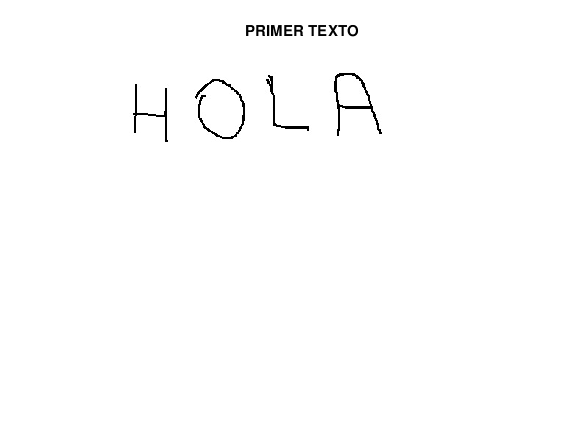

%Lectura del texto y caracteres que vamos a reconocer
clc, close all, clear all
imagen=imread('text1.jpg');
imshow(imagen); title('PRIMER TEXTO');

imagen=rgb2gray(imagen);
threshold=graythresh(imagen); %función utiliza el método de Otsu
imagen=im2bw(imagen); %de escala de grises a binario
imagen=bwareaopen(imagen,30); %Elimina todos los componentes que tengan menos de p pixeles
word=[ ];
re=imagen;
fid=fopen('text.txt','wt') %abrimos el txt donde vamos a escribir

fid = 43

load templates %cargamos el template
global templates %hacemos el template global

num_letras=size(templates,2);
while 1
    [fl re]=lines(re);
    imgn=fl;
    [L Ne] = bwlabel(imgn);
    for n=1:Ne
        [r,c]=find(L==n);
        nl=imgn(min(r):max(r),min(c):max(c));
        imgn_r=imresize(nl,[42,46]);
        letter=read_letter(imgn_r,num_letras);
        word=[word letter];
    end
    fprintf(fid,'%s\n',word);
    word=[];
    if isempty(re)
        break
    end
end

Brace indexing is not supported for variables of this type.

Error in read_letter (line 6)
    sem=corr2(templates{1,n},imagn);

fclose(fid);
winopen('text.txt');